# Q1(A)

Collaborated with: Aditya Rathi

Ruchita Sinha

s = tf('s');
Gnom = 3/(2*s+1);
Gp = (3*exp(-0.1*s))/((2*s+1)*(0.1*s+1)^2);
Gp = pade(Gp,5)

Gp =
 
                                                                                   
               -3 s^5 + 900 s^4 - 126000 s^3 + 1.008e07 s^2 - 4.536e08 s + 9.072e09
                                                                                   
  ----------------------------------------------------------------------------------------------
                                                                                                
  0.02 s^8 + 6.41 s^7 + 965.2 s^6 + 85081 s^5 + 4.494e06 s^4 + 1.299e08 s^3 + 1.576e09 s^2      
                                                                                                
                                                                         + 6.804e09 s + 3.024e09
                                                                                                
 
Continuous-time transfer function.



Gvec = usample(Gp,100);
[P,info] = ucover(Gvec,Gnom,4,'Additive');
P

P =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 5 states.
  The model uncertainty consists of the following blocks:
    Gvec_AddDelta: Uncertain 1x1 LTI, peak gain = 1, 1 occurrences

Type "P.NominalValue" to see the nominal value, "get(P)" to see all properties, and "P.Uncertainty" to interact with the uncertain elements.



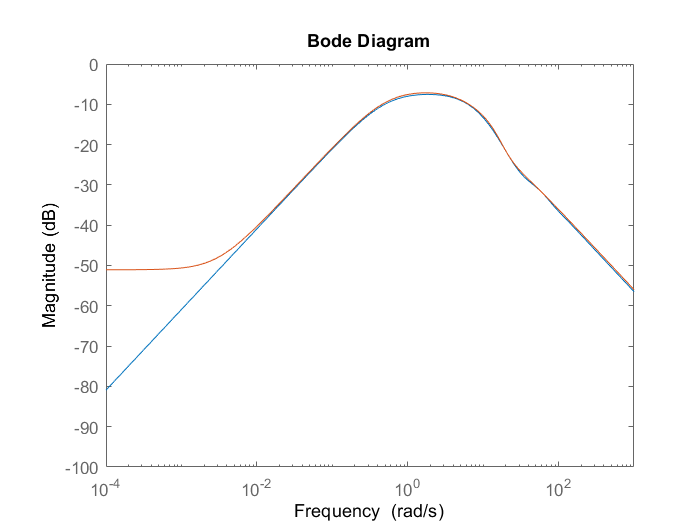

bodemag((Gp-Gnom),info.W1)

Gp-Gnom

ans =
 
                                                                                                
  -0.06 s^8 - 19.23 s^7 - 2902 s^6 - 253446 s^5 - 1.373e07 s^4 - 3.697e08 s^3 - 5.625e09 s^2    
                                                                                                
                                                                                    - 2.722e09 s
                                                                                                
  ----------------------------------------------------------------------------------------------
                                                                                                
  0.04 s^9 + 12.84 s^8 + 1937 s^7 + 1.711e05 s^6 + 9.074e06 s^5 + 2.643e08 s^4 + 3.282e09 s^3   
                                                                                                
                                                          + 1.518e10 s^2 + 1.285e10 s + 3.024e09
                      

info.W1

ans =
 
  A = 
           x1      x2      x3      x4
   x1  -10.16   2.265   10.86  -2.308
   x2   16.68  -8.793  -10.86   2.308
   x3  -8.342    7.66  -1.097  -1.154
   x4   2.085  -1.915   1.906  -6.239
 
  B = 
            u1
   x1    4.579
   x2   -4.579
   x3     2.29
   x4  -0.5724
 
  C = 
            x1       x2       x3       x4
   y1   0.6514   0.1715  -0.9541   -2.753
 
  D = 
              u1
   y1  5.699e-07
 
Continuous-time state-space model.



# Q1(B)

Gp = 10*(-0.5*s+1)/((6*s+1)*(0.2*s+1)*(20*s+1))

Gp =
 
             -5 s + 10
  -------------------------------
  24 s^3 + 125.2 s^2 + 26.2 s + 1
 
Continuous-time transfer function.



G = 10/(6*s + 1)

G =
 
    10
  -------
  6 s + 1
 
Continuous-time transfer function.



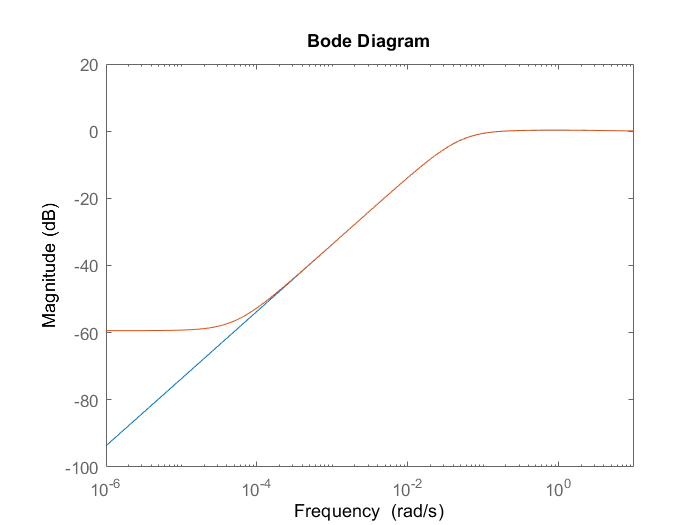

[P,info] = ucover(Gp,G,4);
bodemag((Gp-G)/G,info.W1)

info.W1

ans =
 
  A = 
            x1       x2       x3       x4
   x1   -1.141    1.301   -1.241    1.339
   x2   0.8207   -1.151   0.6204  -0.6696
   x3  -0.8207    1.651    -1.12   0.6696
   x4   0.8207   -1.651     1.62    -1.17
 
  B = 
            u1
   x1    1.411
   x2  -0.7055
   x3   0.7055
   x4  -0.7055
 
  C = 
             x1        x2        x3        x4
   y1   -0.0722   -0.2395  -0.09474    -0.148
 
  D = 
          u1
   y1  1.002
 
Continuous-time state-space model.

